Quiz 7

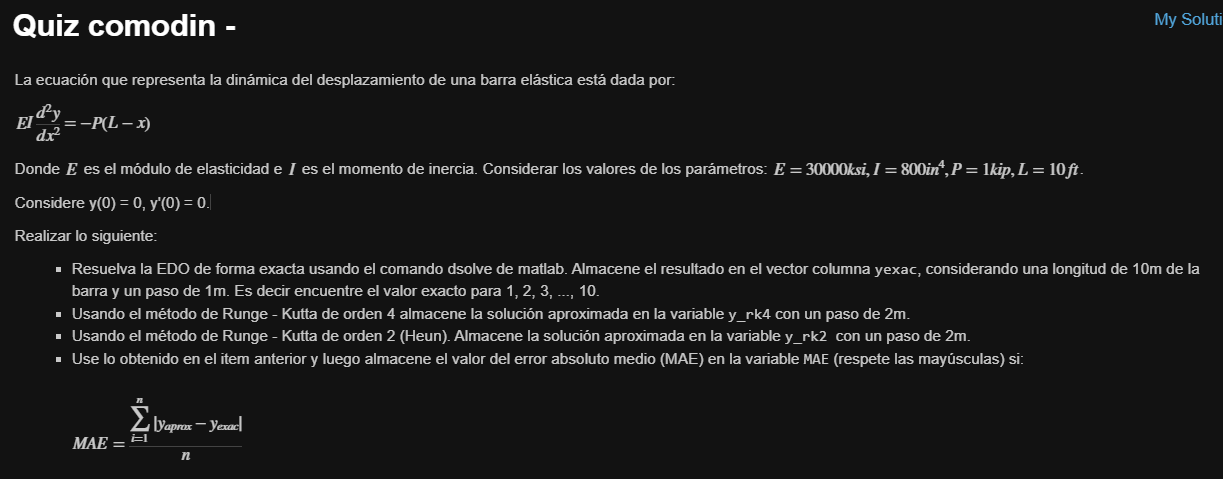

format long
E = 30000;
I = 800;
P = 1;
L = 10;

syms y(x)
D2y = diff(y,2)

$$D2y(x) = \frac{\partial^{2}}{\partial x^{2}}y\left(x\right)$$

Dy = diff(y)

$$Dy(x) = \frac{\partial }{\partial x}y\left(x\right)$$


sol = dsolve(D2y == (-P/(E*I))*(L - x) , y(0) == 0 , Dy(0) == 0)

$$sol = -\frac{3148244321913097\,x\,\left(30\,x-x^{2}\right)}{453347182355485940514816}$$

Sol = matlabFunction( sol )

Sol = function_handle with value:
    @(x)x.*(x.*3.0e+1-x.^2).*(-6.944444444444445e-9)


yexac = [];
for i = 0:10
    yexac = [yexac;Sol(i)];
end

yexac

yexac = 1.0e-04 *

                   0
  -0.002013888888889
  -0.007777777777778
  -0.016875000000000
  -0.028888888888889
  -0.043402777777778
  -0.060000000000000
  -0.078263888888889
  -0.097777777777778
  -0.118125000000000




f = @(x,q,r) (r)

f = function_handle with value:
    @(x,q,r)(r)


g = @(x,q,r) ((-P/(E*I))*(L - x))

g = function_handle with value:
    @(x,q,r)((-P/(E*I))*(L-x))



a = 0;
b = 10;

q0 = 0;
r0 = 0;

h = 2;


[y_rk4 , ~] = rk4_sist(f,g,a,b,q0,r0,h)

y_rk4 = 1.0e-04 *

                   0
  -0.007777777777778
  -0.028888888888889
  -0.060000000000000
  -0.097777777777778
  -0.138888888888889



[y_rk2, ~] = rk2_sist(f,g,a,b,q0,r0,h)

y_rk2 = 1.0e-04 *

                   0
  -0.008333333333333
  -0.030000000000000
  -0.061666666666667
  -0.100000000000000
  -0.141666666666667





MAE = 0;
k = 1;
for i = 1:2:11
    MAE = MAE + abs(y_rk2(k) - yexac(i));
    k = k + 1;
end

MAE = MAE/6

MAE =      1.388888888888888e-07


function [xrk2, yrk2] = rk2_sist(f,g,a,b,x0,y0,h)
    tt = a:h:b; tt = tt';
    x1(1,1) = x0;
    y1(1,1) = y0;
    for i=1:length(tt)-1
        k1x = f(tt(i),x0,y0);
        k1y = g(tt(i),x0,y0);
        k2x = f(tt(i) + h,x0 + h*k1x,y0 + k1y*h);
        k2y = g(tt(i) + h,x0 + h*k1x,y0 + k1y*h);
        x1(i+1,1) = x0 + h*(0.5*k1x + 0.5*k2x);
        y1(i+1,1) = y0 + h*(0.5*k1y + 0.5*k2y);
        x0 = x1(i+1,1);
        y0 = y1(i+1,1);
    end
    xrk2 = x1;
    yrk2 = y1;
end


function [xsol, ysol] = rk4_sist(f,g,a,b,x0,y0,h)
    tt = a:h:b; tt = tt';
    x1(1,1) = x0;
    y1(1,1) = y0;
    for i=1:length(tt)-1
        k1x = f(tt(i),x0,y0);
        k1y = g(tt(i),x0,y0);
        k2x = f(tt(i) + 0.5*h,x0 + 0.5*h*k1x,y0 + 0.5*h*k1y);
        k2y = g(tt(i) + 0.5*h,x0 + 0.5*h*k1x,y0 + 0.5*h*k1y);
        k3x = f(tt(i) + 0.5*h,x0 + 0.5*h*k2x,y0 + 0.5*h*k2y);
        k3y = g(tt(i) + 0.5*h,x0 + 0.5*h*k2x,y0 + 0.5*h*k2y);
        k4x = f(tt(i) + h,x0 + h*k3x,y0 + h*k3y);
        k4y = g(tt(i) + h,x0 + h*k3x,y0 + h*k3y);
        x1(i+1,1) = x0 + (h/6)*(k1x + 2*k2x + 2*k3x + k4x);
        y1(i+1,1) = y0 + (h/6)*(k1y + 2*k2y + 2*k3y + k4y);
        x0 = x1(i+1,1);
        y0 = y1(i+1,1);
    end
    xsol = x1;
    ysol = y1;
end


function x = cifs(A,a)
x = floor(log10( ( 5*abs(A))/abs(A-a) ) );
end